data_filename = 'SBER_stock.csv';
data = readtable(data_filename);
data = table2array(data);

stock = data(:, 2);

dates = datetime(data(:, 1), 'ConvertFrom', 'yyyymmdd');

T = 365;

linear_numerator = 1;
linear_denominator = [T, 1];

linear_filter = tf(linear_numerator, linear_denominator);
linear_filter = ss(linear_filter);

linear_filtered_stock = lsim(linear_filter, stock, 1:1:length(stock), stock(1) / linear_filter.C);

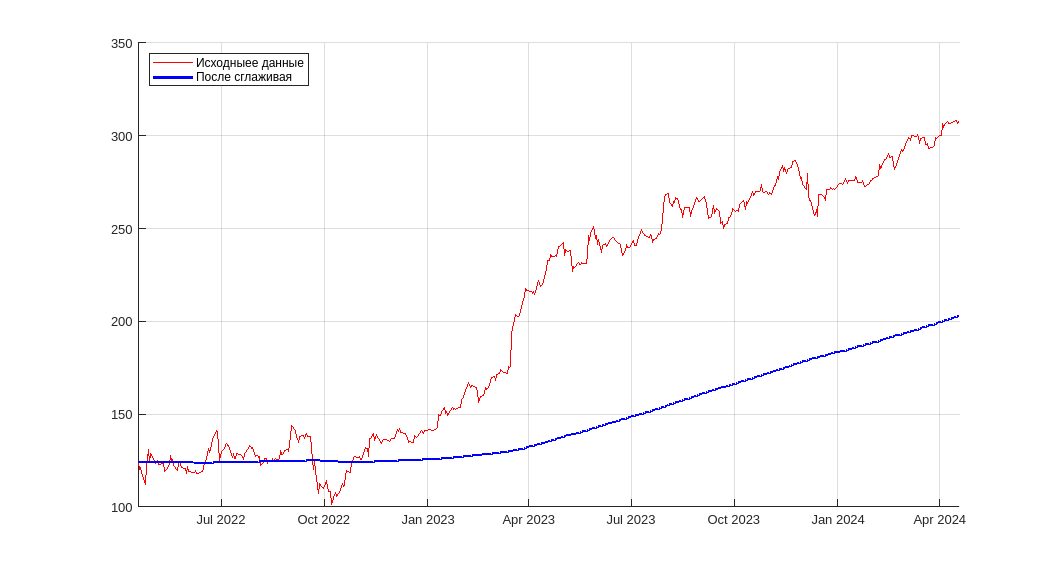

figure;
hold on;
plot(dates, stock, 'r', 'LineWidth', 1);
plot(dates, linear_filtered_stock, 'b', 'LineWidth', 2);
hold off;
xlim('tight');
legend({"Исходныее данные", "После сглаживая"}, 'Location', 'northwest');
grid on;

pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-500 -150 500 150]);